# Homework 1

Name: Denis Mulumba

## Number one

a) Approximation of  $\pi$ using the AGM algorithm.

clear; clc
 a=[];b=[];a(1)=1;b(1)=1/sqrt(2);j=[];j(1)=1;t=[];t(1)=1/4;eps=1e-14;pi_approx=[];
counter=0;
while abs(a(end)-b(end))>=eps
    counter=counter+1;
    y=a(end);
    a(end+1)=(a(end)+b(end))/2;
    b(end+1)=sqrt(b(end)*y);
    t(end+1)=t(end)-j(end)*(a(end)-y)^2;
    j(end+1)=2*j(end);
    pi_approx(counter)=(a(end)^2)/t(end);
end


b) Errors in approximation $\pi$ using AGM 

error=abs(pi-pi_approx);
 format long
Error= error';
Approximate = pi_approx';

Table_of_Results1= table(Approximate, Error)

Table_of_Results1 = 4×2 table
      Approximate              Error        
    ________________    ____________________

    3.18767264271211      0.0460799891223154
    3.14168029329765    8.76397078606317e-05
    3.14159265389545    3.05654168641922e-10
    3.14159265358979    8.88178419700125e-16


c) A plot of errors against the number of iterations

plot( error, 'b-o')
title('An approximate plot of errors against the number of iterations ')
ylabel('Error')
xlabel('Number of iterations(n)')

 The type of covergence observed is Superlinear convergence. 

d) Using vpa function in AGM to compute $\pi$ to 100 digits

digits(100)
a=[];b=[];a(1)=1;b(1)=1/sqrt(2);j=[];j(1)=1;t=[];t(1)=1/4;eps=1e-14;pi_approx=[];
a_vpa=vpa(a);b_vpa=vpa(b);j_vpa=vpa(j);t_vpa=vpa(t);pi_vpa=vpa(pi_approx);
counter2=0;
while abs(a_vpa(end)-b_vpa(end))>=1e-14
    counter2=counter2+1;
    y=a_vpa(end);
    a_vpa(end+1)=(a_vpa(end)+b_vpa(end))/2;
    b_vpa(end+1)=sqrt(b_vpa(end)*y);
    t_vpa(end+1)=t_vpa(end)-j_vpa(end)*(a_vpa(end)-y)^2;
    j_vpa(end+1)=2*j_vpa(end);
    pi_vpa(counter2)=(a_vpa(end)^2)/t_vpa(end);
end

exact=vpa(pi);

error_vpa=abs(exact-pi_vpa);


%%%%%%%%%% Generating the table for AGM with vpa %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Error2= error_vpa';
Approximate2 = pi_vpa';

Result2 = table(Error2, Approximate2);

Four iterations are needed to approximate $\pi$ using vpa in the AGM algorithm

### Number two

Approximating $\exp(x)$ using Taylor series expansion.

The function defined is as follows 

When $n= 10$, the approximated value of $\exp(x)$ and the absolute relative errors are computed for the following values of $x$ as shown below.

x1= -1/2;
exp_aprox1 = approximate_e(x1)

exp_aprox1 =    0.606530659455261


error1 = abs(exp_aprox1 - exp(x1));
absolute_error1 = error1/exp(x1)

absolute_error1 =      4.243359929553495e-10



x2= 1/2;
exp_aprox2  = approximate_e(x2)

exp_aprox2 =    1.648721270418251


error2 = abs(exp_aprox2- exp(x2));
absolute_error2 = error2/exp(x2)

absolute_error2 =      1.709671569516667e-10


x3= -64;
exp_aprox3  = approximate_e(x3)

exp_aprox3 =     -4.344730188914462e+10


error3 = abs(exp_aprox3- exp(x3));
absolute_error3 = error3/exp(x3)

absolute_error3 =      2.709004044378449e+38


x4= 64;
exp_aprox4 = approximate_e(x4)

exp_aprox4 =      6.235030826384401e+27


error4 = abs(exp_aprox4- exp(x4));
absolute_error4= error4/exp(x4)

absolute_error4 =      1.896577382243575e-05


The same funtion to approximte $\exp(x)$ when $n = 40$. 

x1= -1/2;
exp_aprox1 = approximate_e(x1)

exp_aprox1 =    0.606530659712633


error1 = abs(exp_aprox1 - exp(x1));
absolute_error1 = error1/exp(x1)

absolute_error1 =      1.830448315920528e-16


x2= 1/2;
exp_aprox2  = approximate_e(x2)

exp_aprox2 =    1.648721270700128


error2 = abs(exp_aprox2- exp(x2));
absolute_error2 = error2/exp(x2)

absolute_error2 =      2.693537214216206e-16


x3= -64;
exp_aprox3  = approximate_e(x3)

exp_aprox3 =     -8.378449700446133e+23


error3 = abs(exp_aprox3- exp(x3));
absolute_error3 = error3/exp(x3)

absolute_error3 =      5.224088294836307e+51


x4= 64;
exp_aprox4 = approximate_e(x4)

exp_aprox4 =      3.289966279820829e+24


error4 = abs(exp_aprox4- exp(x4));
absolute_error4= error4/exp(x4) 

absolute_error4 =    0.999472351625089


When $n=10$, it is observed that the absolute relative errors are much smaller when $x =$ $\pm \frac{1}{2}$ that those oberved when $x = \pm 64$. However, these approximations become better with increase in $n$. It is therefore safe t say that $p_n$ approximates $\exp(x$$)$ better for larger $n$ and for values of $|x|<1$. 

b) To better approximate $\exp(x)$ for values of $|x$$|$$>>1$, we can think of power property of the exponential funtion, Say, for $-64  \leq x \leq 64$, we can define $\exp(-x) = \frac{1}{\exp(x)}$. The following algorithm can compute the value of $\exp(x)$ $x$ in the interval previously stated.

N = 10;

for j = 1 to length(x) do

     if -1 $\leq$x $\leq$ 1 do

         estimate = 1;

         factorial = 1;

        for i = 1 to N do 

             factorial = factorial * i;

             estimate = estimate + $x^i$ actorial;

         end for

         end if

         if |

This algorith can be implemented for different values of $x$. Below is an implementation of this code for $x = \pm \frac{1}{2}$ and $x = \pm 64$.

x = [-64, -1/2, 1/2, 64];
N = 10;
[approx_better] = p_n(x,N)

approx_better = 1.0e+11 *

   0.000000000000000   0.000000000006065   0.000000000016487   3.753159033665489


exact_values = exp(x);
absolute_error1 = abs(exact_values - approx_better)./exact_values;

absolute_error1 = 1.0e+16 *

   1.661306921684615   0.000000000000000   0.000000000000000   0.000000000000000


c) Dealing with a qutient in the approximation of functions such $\exp(x)$ is better for a better approximation. The code below shows results when an algorithm based on Pade approximation is used for $x \in \bigg[-\frac{1}{2}, \frac{1}{2}\bigg]$.

x = linspace(-1/2,1/2,20);
numerator = (x.^7)/17297280 + (x.^6)/308880 + (x.^5)/11440+ 5*(x.^4)/3432+5*(x.^3)/312+3*(x.^2)/26 +x./2 +1;
denominator = -(x.^7)/17297280 + (x.^6)/308880 - (x.^5)/11440+ 5*(x.^4)/3432-5*(x.^3)/312+3*(x.^2)/26 -x./2 +1;
q_77 = numerator./denominator

q_77 =    0.606530659712633   0.639308330233530   0.673857346798640   0.710273435149254   0.748657494164667   0.789115875424991   0.831760677881875   0.876710058453612   0.924088559405177   0.974027453420301   1.026665107321663   1.082147365446972   1.140627953743172   1.202268905698398   1.267241011291826   1.335724290205328   1.407908490608077   1.483993614896087   1.564190473843372   1.648721270700128


write here

x = linspace(-1/2,1/2,20);
N = 16;
[p_77] = p_n(x,N);

Comparison

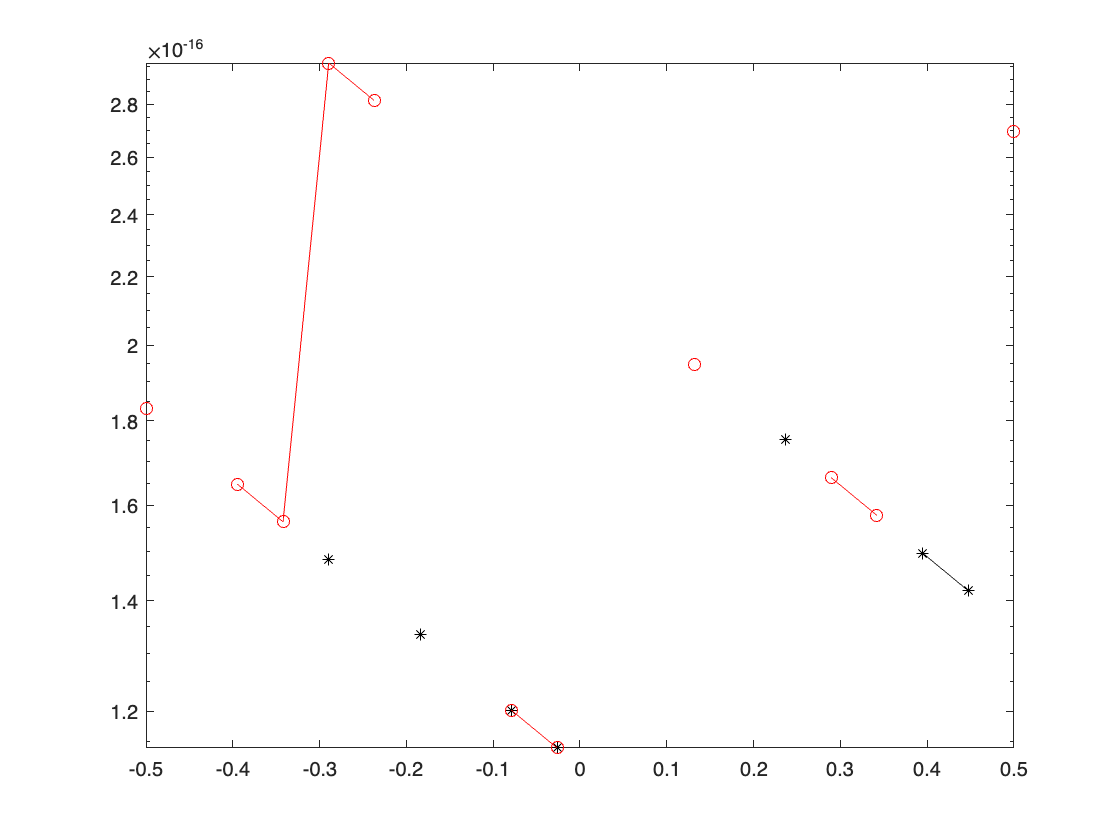

close all
error_q77 = abs(q_77 - exp(x))./exp(x);
error_p77 = abs(p_77 - exp(x))./exp(x);
semilogy(x, error_q77, 'k-*'), hold on
semilogy(x, error_p77, 'r-o')

#### Number three

a)

Given $f(x) = 1 - \tan(x)$ and $g(x) = \frac{\cos(2x)}{\cos^2(1+\tan(x)$, requird is to show that $f(x)$ and $g(x)$ are identical. 

To show this, let us multiply f(x) by  $\frac{1+\tan(x)}{1+\tan(x)$. This yields;

$f(x) = \frac{1 - \tan^2(x)}{1+\tan(x)}$, and with the fact that $\tan^2(x) = \sec^2(x) -1$, we can do further dodification on $f(x)$ by  putting that back into our numerator. and this means that 

$f(x)  = \frac{2 - \sec^2(x)}{1 + \tan(x)}$ = $\frac{2\cos^2(x) - 1}{\cos^2(x) (1+\tan(x)}$, since $\sec(x) = \frac{1}{\cos(x)}$. If we use the double angle formula for the term in the numerator implies that 

$f(x) =  \frac{\cos(2x)}{\cos^2(x)(1+\tan(x)}$ = $g(x)$. There for $f$ ang $g$ are identical.

b) Since $\tan \big(\frac{\pi}{4}\big) = \tan\big(\frac{5\pi}{4}\big) = 1$, this means that $f(x)$ near these alues is approximately zero due to loss of significance errors. There for $g(x)$ should be used used for evaluations near $x = \frac{\pi}{4}$and $x = \frac{5\pi}{4}$.

c) In the same sence, since $g\big(\frac{3\pi}{4}\big) = g\big(\frac{7\pi}{4}\big) = 0$, the function $f(x)$ is suitable to use for values near the stated $x$  values  in order to avoid cancellation errors.

#### Number

#### Number five.

For bigger numbers, we can show that evaluation of the integrals that involve $\tan^{-1}(x)$ may get messy due to loss of signifincance errors. For example, if we evaluate $I(N) = \tan^{-1}(N+1) - \tan^{-1}(N)$ for $N = 10^8$ the result is zero. 

N = 10^8;
I= atan(N+1) - atan(N)

I =      0


However, using properties of the difference of inverse tangents, we can come up with an identical funtion that can account for cancellation errors. 

$\tan^{-1}(N+1) - \tan^{-1}N) = \tan^{-1}\bigg(\frac{N+1 - N}{1+ (N+1)(N)}\bigg)=  \tan^{-1}\bigg(\frac{1}{1-N^2+N}\bigg).$  Implementing this gives the following.

N = 10^8;
I_alternative  = atan(1/(1+(N+1)*N))

I_alternative =      9.999999900000002e-17


#### Function used 

function [approx_better] = p_n(x,N) %funtion for 2b)
approx_better=[];
exact_value = [];
for j=1:length(x)
    if -1<=x(j)<=1
        estimate=1;
        factorial=1;
        for i=1:N
            factorial=factorial*i;
            estimate=estimate+(x(j)^(i))/factorial;
        end
    
   approx_better(j)=estimate;
    end
    if (x(j)<-1)
        estimate1=1;
        factorial1=1;
        for k=1:N
            factorial1=factorial1*k;
            estimate1=estimate1+(abs(x(j))^(k))/factorial1;
        end
    approx_better(j)=estimate1^(-1);
    end

    if (x(j)>1)
        estimate2=1;
        factorial2=1;
        for l=1:N
            factorial2=factorial2*l;
            estimate2=estimate2+(x(j)^(l))/factorial2;
        end
  approx_better(j)=1/estimate2^(-1);
    end
end
end

function [exp_aprox] = approximate_e(x)
%n = 40;
n = 10;
exp_aprox= 1;
factorial = 1;
for j = 1:n-1
    factorial = factorial*j;
    exp_aprox = exp_aprox+ (x^j)/factorial;
end
end
